## Задание 2. Сэмплирование

### ***Сэмплирование синусов***

Исследуем теорему Найквиста-Шеннона-Котельникова на двух примерах...

Но так как эта теорема должна работать на бесконечной числовой оси, которую мы ей не в силах обеспечить, то будем работать  на** большом промежутке**, но показывать малый...

**Задаём начальные параметры**

a1 = 2; a2 = 1;
w1 = 2*pi; w2 = 0.75*pi;
phi1 = 2*pi; phi2 = 1.5*pi;
t = linspace(-100, 100, 18000);
original_delta = t(2) - t(1)

original_delta = 0.0111

y = a1 * sin(w1*t + phi1) + a2 * sin(w2*t + phi2);

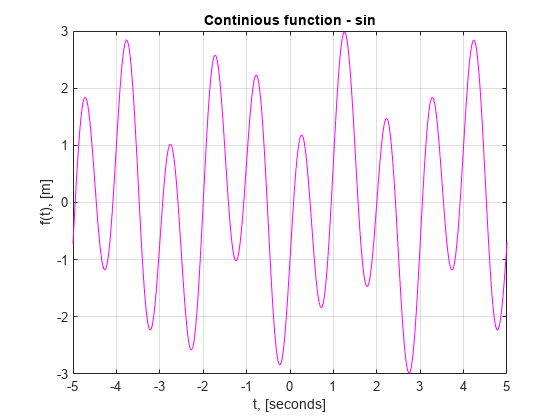

figure;
plot(t, y, 'magenta');
grid on
xlabel('t, [seconds]');
xlim([-5, 5])
title("Continious function - sin")
ylabel('f(t), [m]');
hold off;

counter = 1;
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Посмотрми на сэмплированный вариант указанной функции: рассмотрим разреженный вариант массива времени и соответствующий ему массив значений. **на [-20 ; 20]**

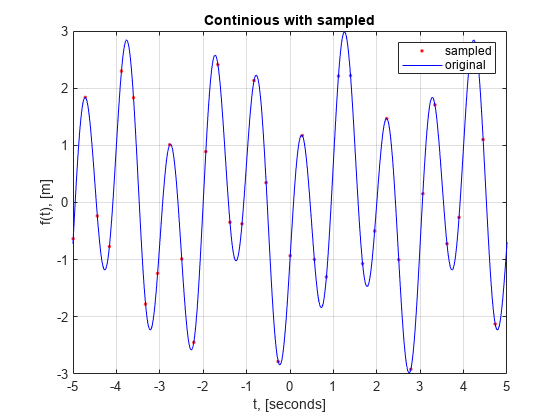

t_sampled = -100:original_delta*25:100;
y_sampled = a1 * sin(w1*t_sampled + phi1) + a2 * sin(w2*t_sampled + phi2);

figure;
plot(t_sampled, y_sampled, 'r.');
xlim([-5, 5])
hold on;
plot(t, y, 'b');
alpha(.5)
grid on
xlabel('t, [seconds]');
title("Continious with sampled")
ylabel('f(t), [m]');
hold off;
legend('sampled','original')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Применим интерполяционную формулу 


$$f\left(t\right)=\sum_{n=-\infty }^{+\infty } f\left(t_n \right)\cdot \textrm{sinc}\left(2B\left(t-t_n \right)\right),\;\;t_n =\frac{n}{2B}$$


 Должны получиться новые массивы времени и значений – той же размерности, что и исходные. Постройте график восстановленной функции поверх исходной.

*Приблизим покрупнее результат, чтобы понять, что мы смогли действительно восстановить исходную функцию в хорошем приближении*

*Также поймём, для того, чтобы определить B нам нужно смотреть на Фурье образ функции*

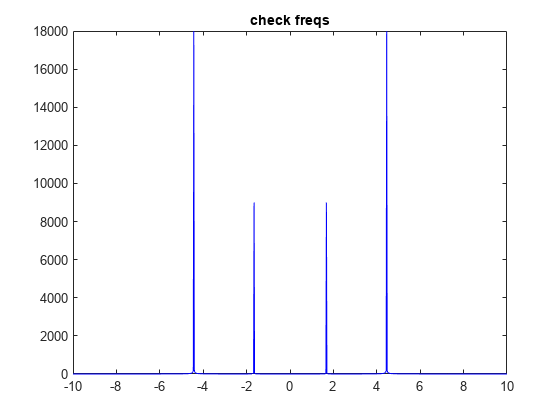

NN = size(t); N = NN(end); V = 200;
v = linspace(-V,V, N); 

figure;
plot(v, abs(fftshift(fft(y))), 'blue');
title('check freqs')
xlim([-10, 10])

fullpath = fullfile(path, "2_check_freqs1");
saveas(gcf, fullpath, 'png'); counter = counter + 1;

*B ~ 0.4  --> *$\Delta t>\frac{1}{2B}=8$

**Большой промежуток и число сэмплов --> успех**

B =  5 % из фурье образа 

B = 5

original_delta

original_delta = 0.0111

delta_n = 1/(2*B)

delta_n = 0.1000

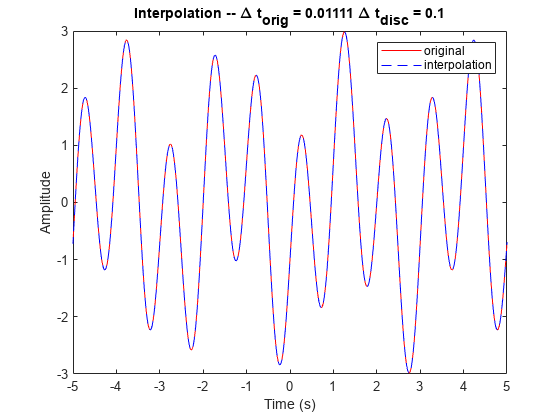

t_n = -100:delta_n:100;
f_n = a1*sin(w1*t_n+phi1) + a2*sin(w2*t_n+phi2);
f = zeros(size(t));

for i = 1:length(t)
    f(i) = sum(f_n .* sinc(2*B*(t(i) - t_n)));
end
figure;
plot(t, y, 'red');
hold on
plot(t, f, '--b');
title("Interpolation -- " + "\Delta t_{orig} = " + round(original_delta,5) + " \Delta t_{disc} = " + round(delta_n, 5));
xlabel('Time (s)');
xlim([-5, 5])
ylabel('Amplitude');
legend('original','interpolation')

fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

**Возьмём B поменьше, обрежем то есть --> плохо всё**

B =  1

B = 1

original_delta

original_delta = 0.0111

delta_n = 1/(2*B)

delta_n = 0.5000

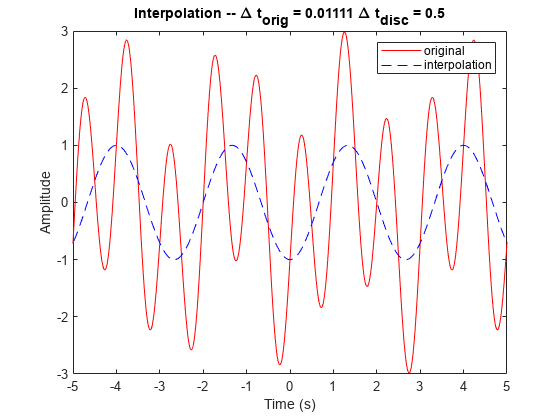

t_n = -100:delta_n:100;
f_n = a1*sin(w1*t_n+phi1) + a2*sin(w2*t_n+phi2);
f = zeros(size(t));

for i = 1:length(t)
    f(i) = sum(f_n .* sinc(2*B*(t(i) - t_n)));
end
figure;
plot(t, y, 'red');
xlim([-5, 5])
hold on
plot(t, f, '--b');
title("Interpolation -- " + "\Delta t_{orig} = " + round(original_delta,5) + " \Delta t_{disc} = " + round(delta_n, 5));
xlabel('Time (s)');
ylabel('Amplitude');
legend('original','interpolation')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

**Ещё больше точек даём --> отлично всё**

B =  3 % из фурье образа 

B = 3

original_delta

original_delta = 0.0111

delta_n = 1/(2*B)

delta_n = 0.1667

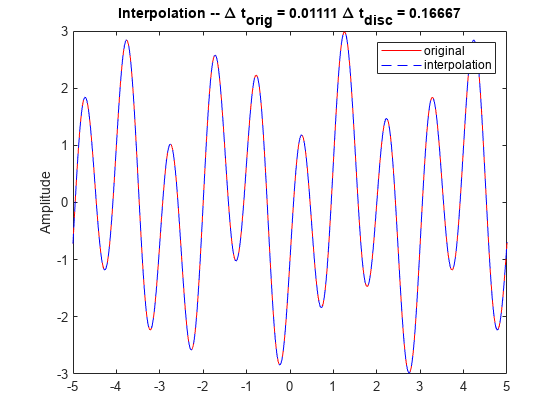

t_n = -100:delta_n:100;
f_n = a1*sin(w1*t_n+phi1) + a2*sin(w2*t_n+phi2);
f = zeros(size(t));

for i = 1:length(t)
    f(i) = sum(f_n .* sinc(2*B*(t(i) - t_n)));
end
figure;
plot(t, y, 'red');
xlim([-5, 5])
hold on
plot(t, f, '--b');
title("Interpolation -- " + "\Delta t_{orig} = " + round(original_delta,5) + " \Delta t_{disc} = " + round(delta_n, 5));
ylabel('Amplitude');
legend('original','interpolation')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

B =  0.5

B = 0.5000

original_delta

original_delta = 0.0111

delta_n = 1/(2*B)

delta_n = 1

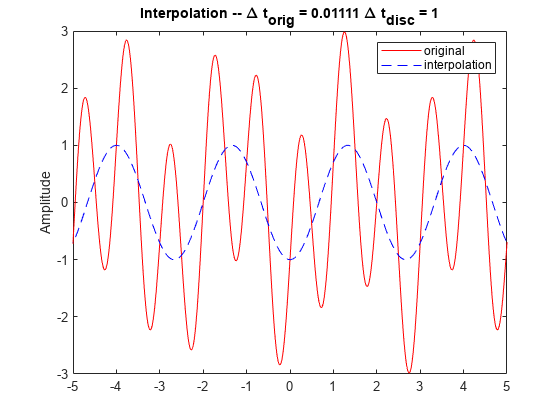

t_n = -100:delta_n:100;
f_n = a1*sin(w1*t_n+phi1) + a2*sin(w2*t_n+phi2);
f = zeros(size(t));

for i = 1:length(t)
    f(i) = sum(f_n .* sinc(2*B*(t(i) - t_n)));
end
figure;
plot(t, y, 'red');
xlim([-5, 5])
hold on
plot(t, f, '--b');
title("Interpolation -- " + "\Delta t_{orig} = " + round(original_delta,5) + " \Delta t_{disc} = " + round(delta_n, 5));
ylabel('Amplitude');
legend('original','interpolation')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;